# Problem 6.6

## a

Ac = [0 1; 0 -1];
Bc = [0 2]';
Cc = [1 0];
Dc = 0;
h = 0.1;
sysc = ss(Ac, Bc, Cc, Dc);
sysd = c2d(sysc, h);


$$\begin{array}{l}
A-\mathrm{BK}=\left\lbrack \begin{array}{cc}
0\; & 1\\
0-2K_1  & -1-2K_1 
\end{array}\right\rbrack \ldotp \;|\left(\mathrm{sI}-A\right)|=\left|\left\lbrack \begin{array}{cc}
s & -1\\
2K_1  & s-\left(1+2K_2 \right)
\end{array}\right\rbrack \right|\\
=s^2 -s\left(1+2K_2 \right)+2K_1 \ldotp \mathrm{Let}\;s_i \;\mathrm{be}\;\frac{\mathrm{ln}\left(\lambda_i \right)}{h}\ldotp \mathrm{Then},\\
s^2 -s\left(1+2K_2 \right)+2K_1 =s^2 -\left(s_1 +s_2 \right)s+s_1 s_2 \ldotp K_1 =\frac{s_1 s_2 }{2}\;\mathrm{and}\;K_2 =\frac{\left(s_1 +s_2 -1\right)}{2}\ldotp \\
K_1 =\frac{\mathrm{ln}\left(\lambda_1 \right)\mathrm{ln}\left(\lambda_2 \right)}{2h^2 }\;\mathrm{and}\;K_2 =\frac{\mathrm{ln}\left(\lambda_1 \lambda_2 \right)-h}{2h}\ldotp \;
\end{array}$$



$$\begin{array}{l}
\bar{\;\Phi } =\Phi -\Gamma K=\left\lbrack \begin{array}{cc}
1-\ldotp 0097K_1  & \ldotp 0952-\ldotp 0097K_2 \\
-\ldotp 1903K_1  & \ldotp 9048-\ldotp 1903K_2 
\end{array}\right\rbrack \ldotp \;\left|\left(\mathrm{zI}-\bar{\;\Phi } \right)\right|=\left|\left\lbrack \begin{array}{cc}
z-\left(1-\ldotp 0097K_1 \right) & -\ldotp \mathrm{0952}+\ldotp 0097K_2 \\
\ldotp 1903K_1  & z-\left(\ldotp 9048-\ldotp 1903K_2 \right)
\end{array}\right\rbrack \right|\\
=\;z^2 -\left(1\ldotp 9048-\ldotp 0097K_1 -\ldotp 1903K_2 \right)z+\left(\ldotp 9048-\ldotp 0088K_1 -\ldotp 1903K_2 +\ldotp 0181K_1 \right)\\
=z^2 -\left(1\ldotp 9048-\ldotp 0097K_1 -\ldotp 1903K_2 \right)z+\left(\ldotp 9048+\ldotp 00934K_1 -\ldotp 1903K_2 \right)=z^2 -\left(\lambda_1 +\lambda_2 \right)z+\lambda_1 \lambda_2 \\

\end{array}$$


## b

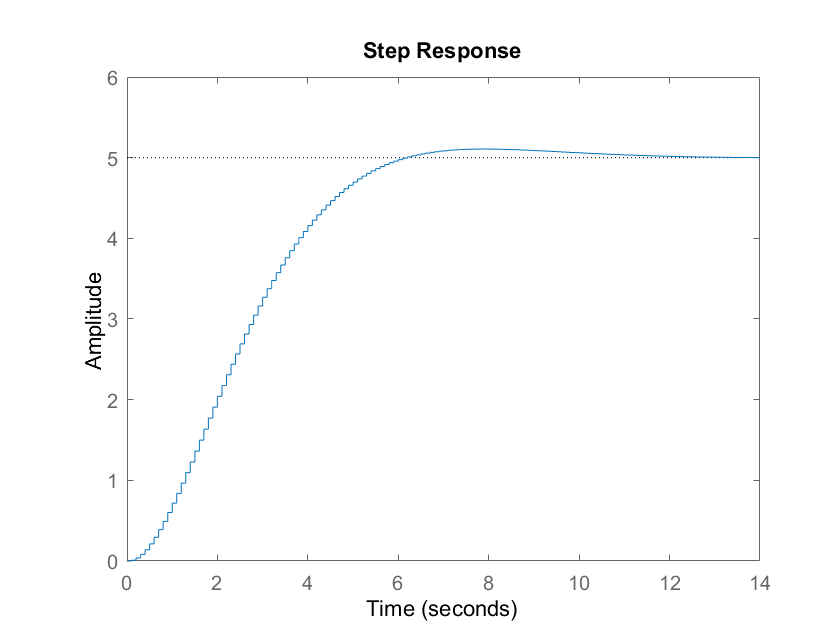

Tz = feedback(sysd, 0.2);
step(Tz);

Overshoot is about 2.2%. 

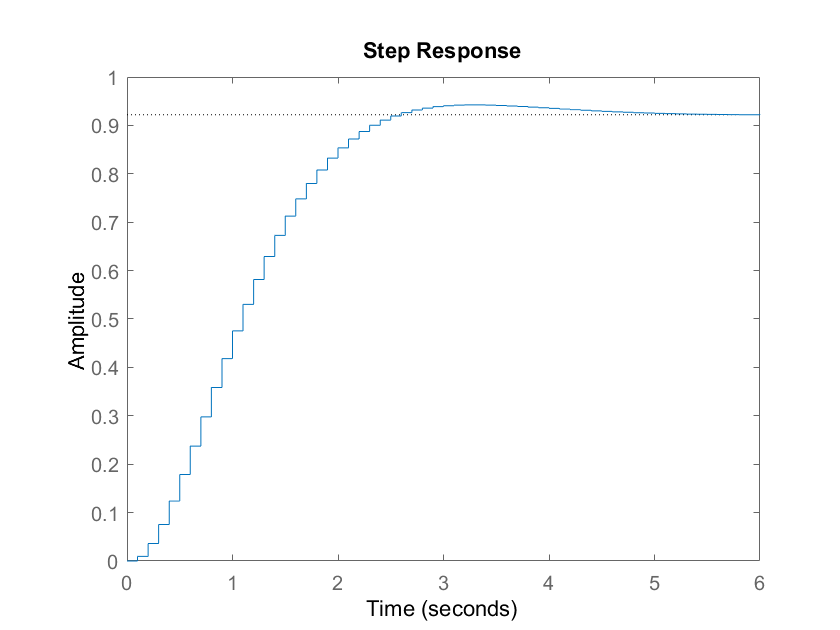


zeta = os2damping(2.2);
tau = .85; % Design for faster response. 
wn = 1/(tau*zeta);
[num, den] = ord2(wn, zeta);
Gs = tf(num, den);
Gz = c2d(Gs, h);
syms K1 K2;
[n, d] = tfdata(Gz, 'v');
eqn1 = 1.9048-.0097*K1 -.1903*K2 == -1*d(2); % FROM denominator of desired Gz
eqn2 = .9048 + .00934*K1 -.1903*K2 == d(3); % FROM denominator of desired Gz
[matA, matB] = equationsToMatrix([eqn1, eqn2], [K1, K2]);
K = linsolve(matA, matB);
K = double(K)';
sysd_compb = ss(sysd.A-sysd.B*K, sysd.B, sysd.C, sysd.D, h);
figure;
step(sysd_compb);

## c

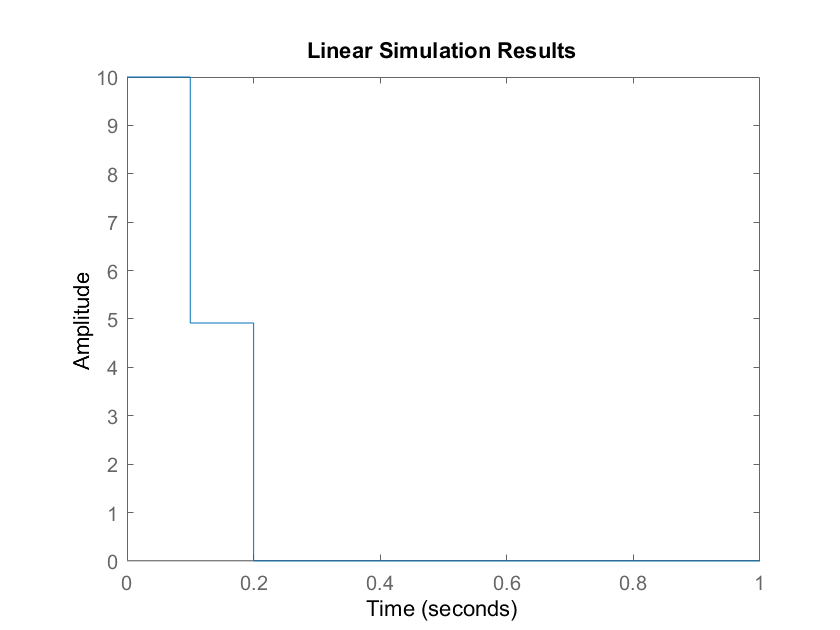

Hc = [sysd.B, sysd.A*sysd.B];
K_deadbeat = [0 1]*inv(Hc)*sysd.A^2;
sysd_compc = ss(sysd.A-sysd.B*K_deadbeat, sysd.B, sysd.C, sysd.D, h);
t = 0: h: 1;
u = 0*t;
figure;
lsim(sysd_compc, u, t, [10 0]');

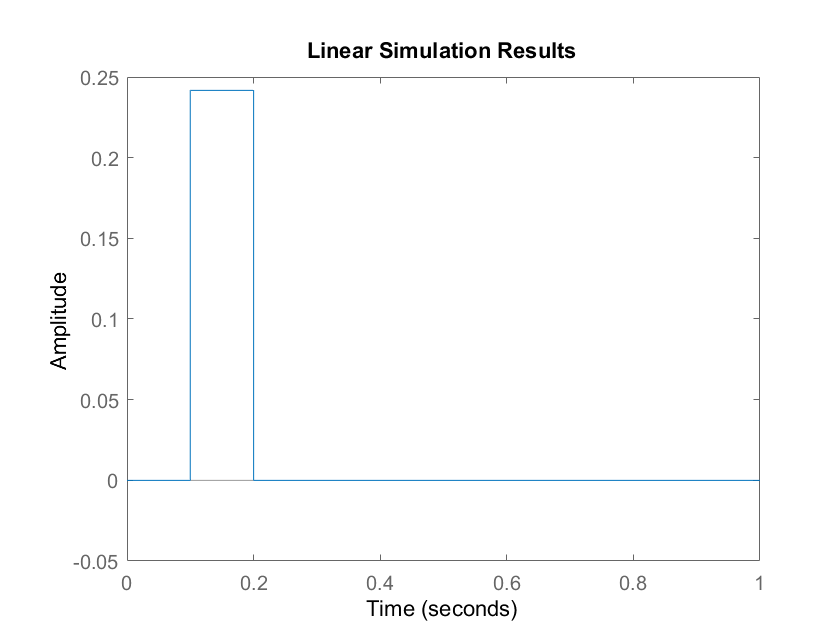

figure;
lsim(sysd_compc, u, t, [0 10]');

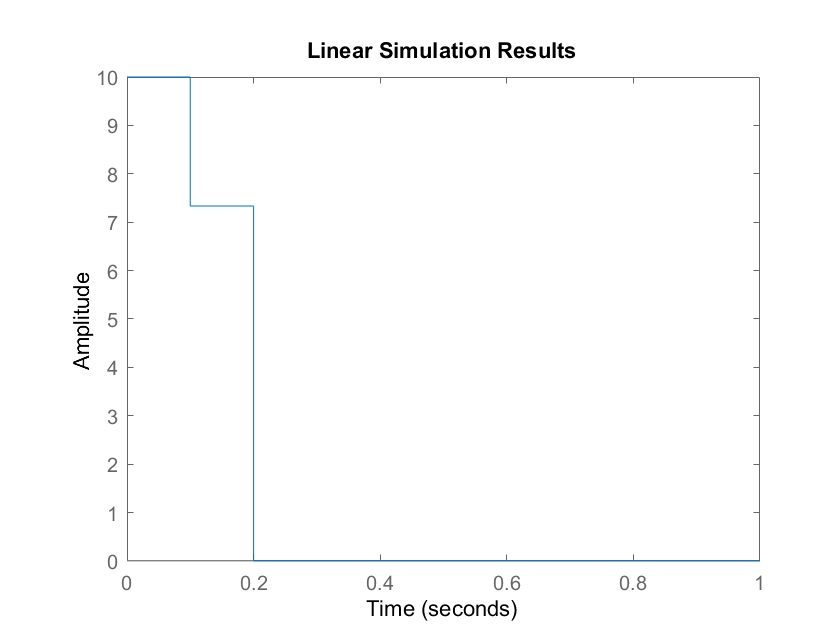

figure;
lsim(sysd_compc, u, t, [10 100]');

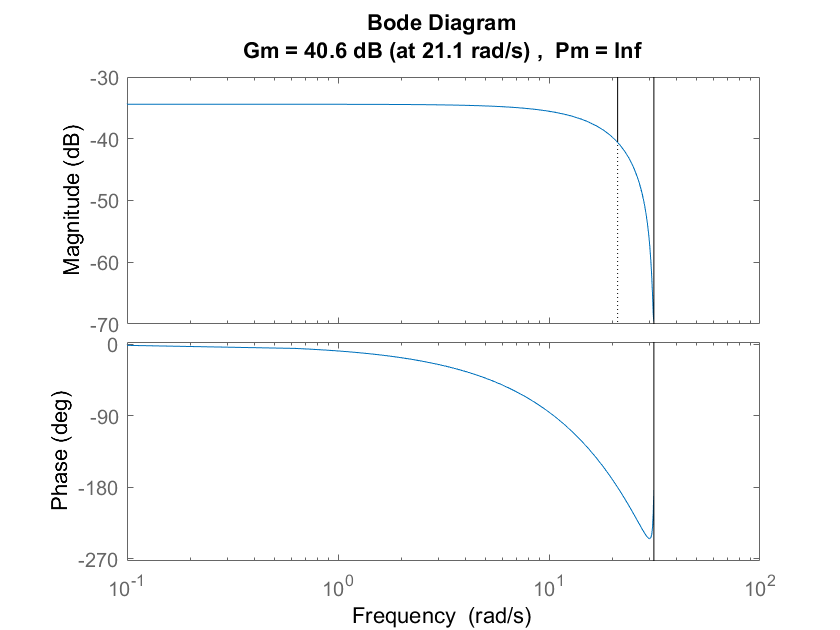

figure;
margin(sysd_compc);


$$\omega_c =\mathrm{DNE},\phi_m =\infty \;\ldotp$$


## d

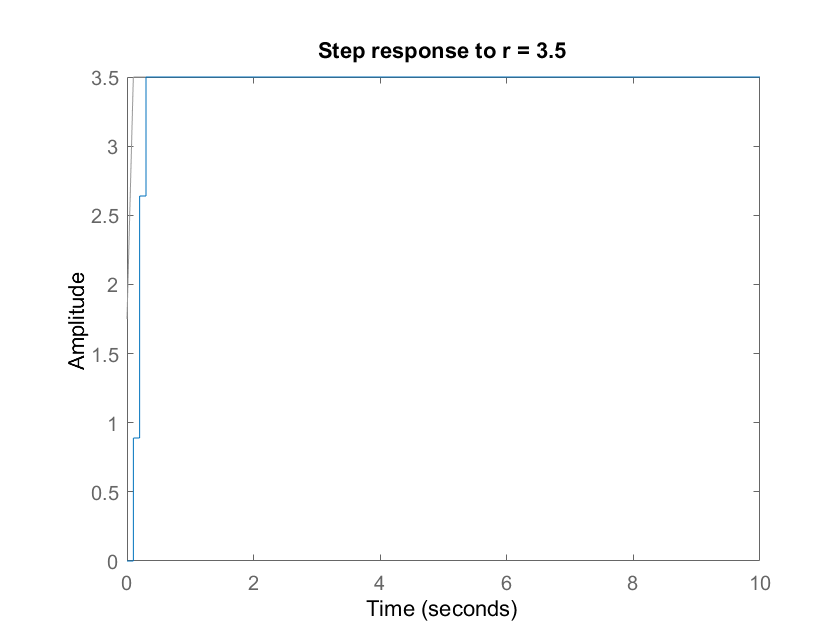

gain = evalfr(sysd_compc.C*inv(z*eye(2)-sysd_compc.A)*sysd_compc.B, 1);
Kr = 1/gain;
sysd_compd = ss(sysd_compc.A, sysd_compc.B*Kr, sysd_compc.C, sysd_compc.D, h);
t = 0: h : 10;
r = 3.5*heaviside(t);
figure;
lsim(sysd_compd, r, t, [0 0]');
title('Step response to r = 3.5')